## encoder

### part 1

characters = ['a':'z', ' ', '.', ',', '!', '"', ';'];

Mapset = cell(32,2);

for i = 1:length(characters)
    Mapset{i,1} = characters(i);
    Mapset{i,2} = dec2bin(i-1,5); 
end
Mapset

Mapset = 32×2 cell array
    {'a'}    {'00000'}
    {'b'}    {'00001'}
    {'c'}    {'00010'}
    {'d'}    {'00011'}
    {'e'}    {'00100'}
    {'f'}    {'00101'}
    {'g'}    {'00110'}
    {'h'}    {'00111'}
    {'i'}    {'01000'}
    {'j'}    {'01001'}
    {'k'}    {'01010'}
    {'l'}    {'01011'}
    {'m'}    {'01100'}
    {'n'}    {'01101'}
    {'o'}    {'01110'}
    {'p'}    {'01111'}
    {'q'}    {'10000'}
    {'r'}    {'10001'}
    {'s'}    {'10010'}
    {'t'}    {'10011'}
    {'u'}    {'10100'}
    {'v'}    {'10101'}
    {'w'}    {'10110'}
    {'x'}    {'10111'}
    {'y'}    {'11000'}
    {'z'}    {'11001'}
    {' '}    {'11010'}
    {'.'}    {'11011'}
    {','}    {'11100'}
    {'!'}    {'11101'}


### part 2

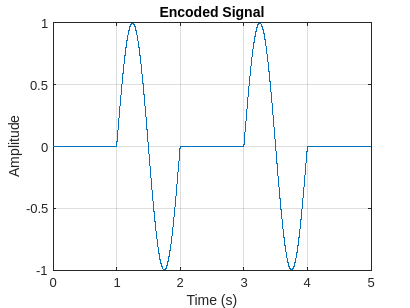

function encodedText = encodeTextWithMapset(Mapset, text)
    % split code and char
    characters = [Mapset{:, 1}];
    codes = Mapset(:, 2);

    % map to char index
    [tmp, idx] = ismember(text, characters);
    
    % encode
    encodedText = strjoin(codes(idx), '');
end

function semgments = segment_massage(transmission_speed, binary_message)
    semgments = {};
    for i = 1:transmission_speed:strlength(binary_message)
        if i + transmission_speed - 1 <= strlength(binary_message)
            segment = binary_message(i:i+transmission_speed-1);
        else
            segment = binary_message(i:end);
        end
       semgments{end+1} = segment;
    end
end

function signal = binaryToSignal(segment, t, transmission_speed)
    max_value = 2^transmission_speed - 1;
    signal = zeros(size(t));

    for i = 0:max_value
        if strcmp(dec2bin(i, transmission_speed), segment)
            signal = (i / max_value) * sin(2 * pi * t);
        end
    end
end

function encoded_message = convert_to_signal(semgments, transmission_speed)
    global SAMPLEPERSEC;
    t = linspace(0, 1, SAMPLEPERSEC);
    
    encoded_message = zeros(1, length(t) * length(semgments));

    for i = 1:length(semgments)
       segment = semgments{i};
       signal = binaryToSignal(segment, t, transmission_speed);
        start_idx = (i-1)*length(t) + 1;
        end_idx = i*length(t);
        encoded_message(start_idx:end_idx) = signal;
    end
end

function encoded_message = coding_amp(message, transmission_speed, Mapset)
    message = char(message);
    binary_message = encodeTextWithMapset(Mapset,message);

    semgments = segment_massage(transmission_speed, binary_message);

    encoded_message = convert_to_signal(semgments, transmission_speed);

end

global SAMPLEPERSEC;
SAMPLEPERSEC = 1000;
message = 'k';
speed = 1;
encoded_message = coding_amp(message, speed, Mapset);

t = linspace(0, length(encoded_message)/SAMPLEPERSEC, length(encoded_message)); 
plot(t, encoded_message);
xlabel('Time (s)');
ylabel('Amplitude');
title('Encoded Signal');
grid on;